Get values

% Set up the Import Options and import the data
opts2 = delimitedTextImportOptions("NumVariables", 4);

% Specify range and delimiter
opts2.DataLines = [2, Inf];
opts2.Delimiter = " ";

% Specify column names and types
opts2.VariableNames = ["E_in_p1", "Var2", "Var3", "Var4"];
opts2.VariableTypes = ["double", "double", "double", "double"];

% Specify file level properties
opts2.ExtraColumnsRule = "ignore";
opts2.EmptyLineRule = "read";
opts2.LeadingDelimitersRule = "ignore";

% Import the data
UI2 = readtable("C:\Users\Jinne\Documents\Jinne\FEFE\FEFE_VOL_LAB\FEFE_LAB\UI.txt", opts2);

% Convert to output type
UI2 = table2array(UI2);

% Clear temporary variables
clear opts2

% Display results
UI2

UI2 = 1.0e+04 *

       NaN       NaN       NaN    1.0011
    0.0050    0.2400         0       NaN
       NaN       NaN       NaN    1.0011
    0.0050   -0.0050    0.0088       NaN
       NaN       NaN       NaN       NaN
       NaN       NaN       NaN    1.0021
    0.0050   -0.1200    0.2078       NaN
       NaN       NaN       NaN    1.0021
    0.0050   -0.0086    0.0098       NaN
       NaN       NaN       NaN       NaN


UI2(26,2)

ans = 319.3625

UI2(28,2)

ans = 221.7795

Exterior characteristcs

PF = 1

Done for our phase 2 all values are measured at the secondary side



Ur = [266.6086; 300.0138; 321.509; 338.134; 351.8289 ];
Ir = [617.1496; 462.9843; 372.1169; 313.087; 271.4729];

Uc =[407.6660;407.6660;407.6660;407.6660;407.6660;]; 
Ic =[0;0;0;0;0;];

Ui = [2.3014e-14];%practically a short-circuit
Ii = [1076];


PF =0.8

Ur = [266.6086; 300.0138; 321.509; 338.134; 351.8289 ];
Ir = [617.1496; 462.9843; 372.1169; 313.087; 271.4729];

Uc = [323.2344; 228.4684; 319.3625; 987.4445; 5804.9];
Ic = [448.9366; 211.5448; 221.7795; 548.5803; 2687.5];

Ui = [138.3414; 168.5075; 190.3097; 207.2076; 220.9163];
Ii = [533.7244; 433.4041; 367.1099; 319.7648; 284.1002];


PF = 0.6

Ur = [266.6086; 300.0138; 321.509; 338.134; 351.8289 ];
Ir = [617.1496; 462.9843; 372.1169; 313.087; 271.4729];

Uc = [487.6369; 285.8; 228.5; 267.9; 519.4];
Ic = [903.0312; 352.9; 211.5; 198.4; 320.6];

Ui = [159.6402; 190.3; 212.1; 228.8; 242.2 ];
Ii = [461.9219; 167.1; 306.8; 264.8; 233.6];


PF =0.4

Ur = [266.6086; 300.0138; 321.509; 338.134; 351.8289 ];
Ir = [617.1496; 462.9843; 372.1169; 313.087; 271.4729];

Uc = [696.3; 329.9; 248.9; 227.43; 301.9];
Ic = [1472.2; 466.6; 264.1; 193.0; 213.5];

Ui = [169.9; 200.6; 222.3; 238.8; 252.1];
Ii = [429.1; 337.8; 280.7; 241.3; 212.3];


PF =0.2

Ur = [266.6086; 300.0138; 321.509; 338.134; 351.8289 ];
Ir = [617.1496; 462.9843; 372.1169; 313.087; 271.4729];

Uc = [931.6; 357; 268.7; 227.1; 256.9];
Ic = [2112.9; 539.8; 299; 206; 194.2];

Ui = [174.9; 205.6; 227.3; 243.7; 256.9];
Ii = [413.3; 323.9; 268.5; 230.3; 202.3];

PF = 0

Ur = [266.6086; 300.0138; 321.509; 338.134; 351.8289 ];
Ir = [617.1496; 462.9843; 372.1169; 313.087; 271.4729];

Uc = [1049.8; 366.4; 268.7; 228.5; 248.0]

Uc = 1.0e+03 *

    1.0498
    0.3664
    0.2687
    0.2285
    0.2480


Ic = [2430.2; 565.3; 311; 211.5; 191.4]

Ic = 1.0e+03 *

    2.4302
    0.5653
    0.3110
    0.2115
    0.1914



Ui = [176.5; 207.2 ;228.8; 245.2; 258.4]

Ui =   176.5000
  207.2000
  228.8000
  245.2000
  258.4000


Ii = [408.5; 319.8; 264.8; 227.1; 199.4]

Ii =   408.5000
  319.8000
  264.8000
  227.1000
  199.4000


Analysis Resistive

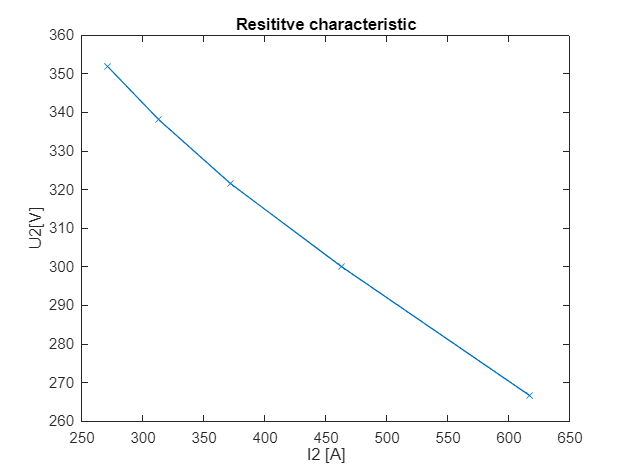

Ur = [266.6086; 300.0138; 321.509; 338.134; 351.8289 ];
Ir = [617.1496; 462.9843; 372.1169; 313.087; 271.4729];

figure
plot(Ir,Ur,'-x')
xlabel('I2 [A]')
ylabel('U2[V]')
title('Resititve characteristic')

Analysis Capacitive

%pf = 1
Uc =[407.6660]; 
Ic =[0];

figure
hold on
plot(Ic,Uc,'-xr')

Error using plot
Invalid color, marker, or line style.

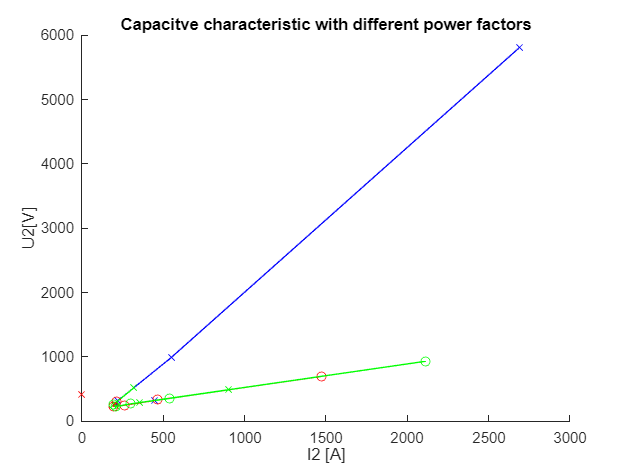

xlabel('I2 [A]')
ylabel('U2[V]')
title('Capacitve characteristic with different power factors')

%pf =0.8
Uc = [323.2344; 228.4684; 319.3625; 987.4445; 5804.9];
Ic = [448.9366; 211.5448; 221.7795; 548.5803; 2687.5];
plot(Ic,Uc,'-xb')

%pf =0.6
Uc = [487.6369; 285.8; 228.5; 267.9; 519.4];
Ic = [903.0312; 352.9; 211.5; 198.4; 320.6];
plot(Ic,Uc,'-xg')

%pf =0.4
Uc = [696.3; 329.9; 248.9; 227.43; 301.9];
Ic = [1472.2; 466.6; 264.1; 193.0; 213.5];
plot(Ic,Uc,'-or')

%pf =0.2
Uc = [931.6; 357; 268.7; 227.1; 256.9];
Ic = [2112.9; 539.8; 299; 206; 194.2];
plot(Ic,Uc,'-og')